# 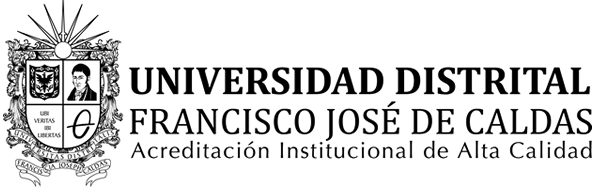

# **Taller Newton Rapson.**

## **Nombres:**

## John Fredy Pinilla Morales - 20192007072

## **Cristian David Cuervo Gonzalez-20192007068 **

## **Lizeth Johanna Robayo Usme -**20191007010

clc;clear;

%e=input('ingrese el error maximo');
%iterMAX=input('Ingrese el número de iteraciones maximas para lograr el error');
% nodos=input('Ingrese número de nodos:');
% lineas=input('Ingrese número de ramas:');
% L=zeros(lineas,5);
% N=zeros(nodos,8);
% for K=1:nodos
%     N(K,1)=K;
% end
% for K=1:nodos
%     fprintf(['ingrese que tipo de nodo (slack=0 PV=1 PQ=2) es el nodo %i\n'],K);
%     N(K,2)=input('');
% end
% for K=1:nodos
%     fprintf('ingrese la potencia activa generada en el nodo %i:',K);
%     N(K,3)=input('');
%     fprintf('ingrese la potencia reactiva generada en el nodo%i:',K);
%     N(K,4)=input('');
%     fprintf('ingrese la potencia activa demandada en el nodo %i:',K);
%     N(K,5)=input('');
%     fprintf('ingrese la potencia reactiva demandada en el nodo %i:',K);
%     N(K,6)=input('');
%     fprintf('ingrese la magnitud de la tension en el nodo %i:',K);
%     N(K,7)=input('');
%     fprintf('ingrese el angulo de la tension en el nodo %i:',K);
%     N(K,8)=input('');
% end
% 
% for k=1:lineas
% fprintf('para la rama %i ingrese los nodos donde se conecta \n',k);
% fprintf('ingrese el nodo inicial:');
% L(k,1)=input('');
% fprintf('ingrese el nodo Final:');
% L(k,2)=input('');
% end
% for k=1:lineas
% fprintf('para la rama %i ingrese la conductancía\n',k);
% L(k,3)=input('');
% fprintf('para la rama %i ingrese la suceptancia\n',k);
% L(k,4)=input('');
% fprintf('para la rama %i ingrese el valor de Yc/2 \n',k);
% L(k,5)=input('');
% end
% L
Sbase=100;%MVA
VB=230;%KV
%[K M   Rkm     Xkm     Yc/2]
L=[1 2 0.01008 0.05040 0.05125;
    1 3 0.00744 0.03720 0.03875;
    2 4 0.00744 0.03720 0.03875;
    3 4 0.01272 0.06360 0.06375];
%T slack=0 PV=1 PQ=2
%[K T Pgk Qgk Pck Qck    V    A]
N=[1 0 0   0   50  30.990 1    0;
    2 2 0   0   170 105.35 1    0;
    3 2 0   0   200 123.94 1    0;
    4 1 318 0   80  49.580 1.02 0];

N(:,3:6)=N(:,3:6)/Sbase;
N

N =     1.0000         0         0         0    0.5000    0.3099    1.0000         0
    2.0000    2.0000         0         0    1.7000    1.0535    1.0000         0
    3.0000    2.0000         0         0    2.0000    1.2394    1.0000         0
    4.0000    1.0000    3.1800         0    0.8000    0.4958    1.0200         0


L

L =     1.0000    2.0000    0.0101    0.0504    0.0512
    1.0000    3.0000    0.0074    0.0372    0.0387
    2.0000    4.0000    0.0074    0.0372    0.0387
    3.0000    4.0000    0.0127    0.0636    0.0638


## Ybarra

FL= size(L,1);
FN= size(N,1);
Ybarra=zeros(FN,FN);
for j=1:FL
    K=L(j,1);M=L(j,2);Zkm=L(j,3)+1j*L(j,4);Yc=1j*L(j,5);
    Ybarra(K,M)=-1/Zkm;%Triangular Superior
    Ybarra(M,K)=-1/Zkm;%Triangular Inferior
    Ybarra(K,K)=Ybarra(K,K)+1/Zkm+Yc;%Elementos dte la diagonal
    Ybarra(M,M)=Ybarra(M,M)+1/Zkm+Yc;%Elementos de la diagonal
end
Ybarra

Ybarra =    8.9852 -44.8360i  -3.8156 +19.0781i  -5.1696 +25.8478i   0.0000 + 0.0000i
  -3.8156 +19.0781i   8.9852 -44.8360i   0.0000 + 0.0000i  -5.1696 +25.8478i
  -5.1696 +25.8478i   0.0000 + 0.0000i   8.1933 -40.8638i  -3.0237 +15.1185i
   0.0000 + 0.0000i  -5.1696 +25.8478i  -3.0237 +15.1185i   8.1933 -40.8638i


## Newton Rapson

V0=N(:,7);
VA=N(:,8);
VAN=VA;
V0N=V0;
iterMAX= input('Ingrese el número de iteraciones maximas para lograr el error: ');
for t=1:iterMAX
%Obteniendo la potencia activa y reactiva
FP=0;        % # Filas de la matriz de potencias calculadas
NPQ=0;       % # De nodos PQ
NPV=0;       % # De nodos PV
for j=1 :FN  % Se crea la matriz de potencias y su dimencion depende de el # de nodos pv y pq
    H=N(j,2);FP=H+FP;
    if H==2
        NPQ=NPQ+1;
    end
    if H==1
        NPV=NPV+1;
    end
end
P=zeros(FP,1);
Pn=zeros(FP,1);
Po=zeros(FP,1);
JA=zeros(FP,FP);
%Creando matrizes para almacenar los valores actualizados de magnitud y
%angulo de tension
%CREANDO VECTOR DE POTENCIAS INICIALES
V=1; 
for j=1:FN
    if N(j,2)==2||N(j,2)==1
        Po(V,1)=N(j,3)-N(j,5);
        V=V+1;
        
    end
end
for j=1:FN
    if N(j,2)==2
        Po(V,1)=N(j,4)-N(j,6);
        V=V+1;
    end
end
%_______________________________
i=1;% Contador para llevar la cuenta de los numeros que colocan en la matriz P
F=1; %Controla la posicion de las filas del jacobiano
for j=1:FN
    if N(j,2)==2||N(j,2)==1
        for t=1:FN
            if real(Ybarra(j,t))~=0 && imag(Ybarra(j,t))~=0                                                                                 %Con este if solo se corrige 1 excepcion faltan 3 para p y 3 para Q 
        P(i,1)=N(j,7)*N(t,7)*abs(Ybarra(j,t))*cos(N(t,8)-N(j,8)+angle(Ybarra(j,t)));% hallando P calculada. El valor de p calculada queda en Pn y no en P
        Pn(i,1)=P(i,1)+Pn(i,1);
            end
        end
        i=i+1;
    end
        Q=1;   %Controla la posicion de las columnas del jacobiano
        if N(j,2)==2||N(j,2)==1
        for t=1:FN   
            if N(t,2)==2||N(t,2)==1
                JA(F,Q)=1; %Calcula valores de la matriz H
            Q=1+Q;
             end
            end
            for t=1:FN 
                if N(t,2)==2
                    JA(F,Q)=2;% Calcula valores de la matriz N 
                    Q=1+Q;
             end
            end
           F=F+1;
        end 
        
end
%_______________________________
for j=1:FN
        Q=1;   %Controla la posicion de las columnas del jacobiano
        if N(j,2)==2
        for t=1:FN   
            if N(t,2)==2||N(t,2)==1
                JA(F,Q)=3; %Calcula valores de la matriz J
            Q=1+Q;
             end
            end
            for t=1:FN 
                if N(t,2)==2
                    JA(F,Q)=4;% Calcula valores de la matriz L 
                    Q=1+Q;
             end
            end
           F=F+1;
        end 
        
end
%_______________________________

for j=1:FN
    if N(j,2)==2
         for t=1:FN
         if real(Ybarra(j,t))~=0 && imag(Ybarra(j,t))~=0                                                                                     %Faltan restricciones
         P(i,1)=(-1)*(N(j,7)*N(t,7)*abs(Ybarra(j,t))*sin(N(t,8)-N(j,8)+angle(Ybarra(j,t))));%Hallando Q calculada. El valor de Q calculada queda en Pn y no en P
         Pn(i,1)=P(i,1)+Pn(i,1);
            end
         end   
         i=i+1;
    end
end
deltaP=Po-Pn;
VA=VAN;
V0=V0N;
deltaP
JA
end

deltaP =    -1.5966
   -1.9395
    2.2129
   -0.4465
   -0.8345


JA =      1     1     1     2     2
     1     1     1     2     2
     1     1     1     2     2
     3     3     3     4     4
     3     3     3     4     4
